### **Step 5: Convert gTruth object into Data**

load bookgTruth.mat  % To lode the labeled data


trainingDatabook = objectDetectorTrainingData(bookgTruth,'SamplingFactor',1,...
    'WriteLocation','TrainingData');
% Display first few rows of the data set.
trainingDatabook(1:4,:)

ans = 4×2 table
                                              imageFilename                                                               book                 
    __________________________________________________________________________________________________    _____________________________________

    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 001_output.jpeg'}    {[                    314 45 96 267]}
    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 002_output.jpeg'}    {[     314.0000 45.0000 96.0000 267]}
    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 003_output.jpeg'}    {[313.6519 44.6315 95.9659 266.5939]}
    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 004_output.jpeg'}    {[313.6520 44.6316 95.9658 266.5937]}


load facegTruth.mat  % To lode the labeled data


trainingDataface = objectDetectorTrainingData(facegTruth,'SamplingFactor',1,...
    'WriteLocation','TrainingData');
% Display first few rows of the data set.
trainingDataface(1:4,:)

ans = 4×2 table
                                              imageFilename                                                                Face                 
    __________________________________________________________________________________________________    ______________________________________

    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 001_output.jpeg'}    {[                    209 113 70 190]}
    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 002_output.jpeg'}    {[208.9451 113.0769 69.9780 189.8352]}
    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 003_output.jpeg'}    {[208.8901 113.1538 69.9560 189.6703]}
    {'C:\Users\vaish\Documents\MATLAB\Data Labeling\yolo2\ResizedTrainImages\RedBook 004_output.jpeg'}    {[208.8352 113.2308 69.9341 189.5055]}


### **Step 6 : Design and Train YOLOv2 in MATLAB **


inputLayer = imageInputLayer([128 128 3],'Name','input','Normalization','none');
filterSize = [3 3];
middleLayers = [
    convolution2dLayer(filterSize, 16, 'Padding', 1,'Name','conv_1',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN1')
    reluLayer('Name','relu_1')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1,'Name', 'conv_2',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN2')
    reluLayer('Name','relu_2')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1,'Name','conv_3',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1,'Name','conv_4',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN4')
    reluLayer('Name','relu_4')
    ];


lgraph = layerGraph([inputLayer; middleLayers]);
numClasses = size(trainingDataface,2) - 1;




Anchor Size may differ for Different data sets. Need to know how to decide the anchors size 


Anchors = [43 59
    18 22
    23 29
    84 109];

lgraph = yolov2Layers([128 128 3],numClasses,Anchors,lgraph,'relu_4');
analyzeNetwork(lgraph);


### **Step 7 : Train the Network**


doTraining = false;
% setting this flag to true will build and train a YOLOv2 detector
% false will load a pre-trained network
 
if doTraining
     options = trainingOptions('sgdm', ...
        'InitialLearnRate',0.001, ...
        'Verbose',true,'MiniBatchSize',16,'MaxEpochs',20,...   %set no of epocs to 80
        'Shuffle','every-epoch','VerboseFrequency',50, ...
        'DispatchInBackground',true,...
        'ExecutionEnvironment','auto');
     
     [detectorBookYolo, info] = trainYOLOv2ObjectDetector(trainingDatabook,lgraph,options);   
     save detectorBookYolo
     
     [detectorFaceYolo, info] = trainYOLOv2ObjectDetector(trainingDataface,lgraph,options);  
     save detectorFaceYolo
     
    
else
    load detectorBookYolo.mat
    load detectorFaceYolo.mat
    
end

### **Step 8 : Use it on Test Data **

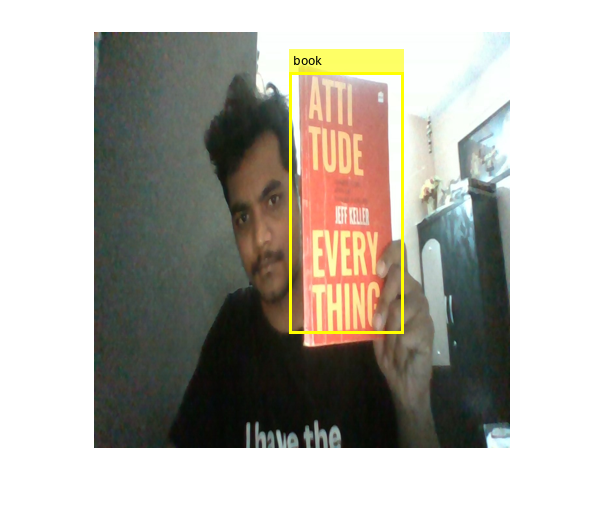

% Read the image
I = imread("C:\Users\vaish\Documents\MATLAB\Data Labeling\YOLO1\TestImage.jpg");
I = imresize(I, [416 416]);
    
% Run the detector.
%[bboxes,scores,labels] = detect(detectorFaceYolo,I);
[bboxes1,scores1,labels1] = detect(detectorBookYolo,I);

%I = insertObjectAnnotation(I,'Rectangle',bboxes,cellstr(labels),"LineWidth",3);
I = insertObjectAnnotation(I,'Rectangle',bboxes1,cellstr(labels1),"LineWidth",3);

imshow(I);

## **On webcam**

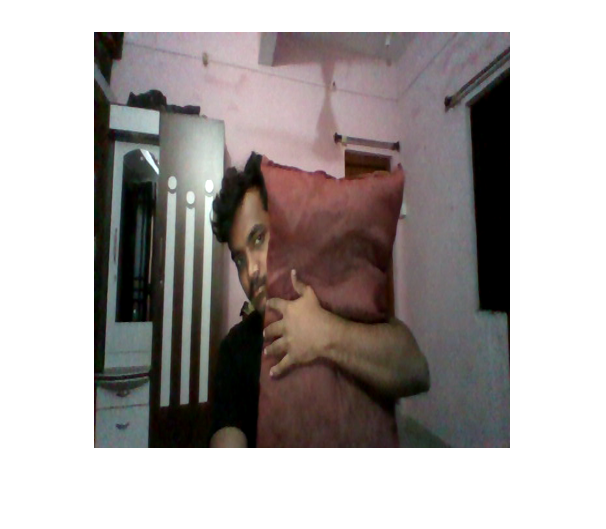

clear("web")
web  = webcam;

I = snapshot(web);
clear("web") %to turn off the camera
I = imresize(I, [416 416]);
[bboxes,scores,labels] = detect(detectorBookYolo,I);
[bboxes1,scores1,labels1] = detect(detectorBookYolo,I);

I = insertObjectAnnotation(I,'Rectangle',bboxes,cellstr(labels),"LineWidth",3);
%I = insertObjectAnnotation(I,'Rectangle',bboxes1,cellstr(labels1),"LineWidth",3);

imshow(I);